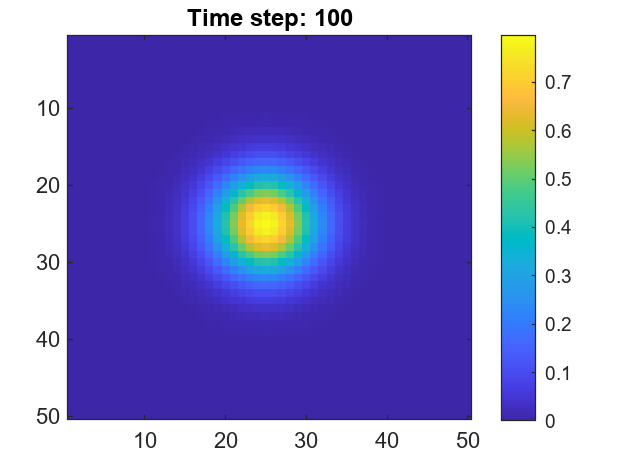

%% Exercise 9: 
% Use the interpretation of the Laplacian operator for the heat equation 
% presented in the PDE lecture to develop a cellular automata in MATLAB for heat transfer and diffusion models. 
% Simulate the proposed model with various boundary conditions.

% Setting parameters
m = 50; % Number of rows in the grid
n = 50; % Number of columns in the grid
D = 1; % Diffusion coefficient
dt = 0.1; % Time step size
dx = 1; % Spatial step size in x direction
dy = 1; % Spatial step size in y direction
timesteps = 100; % Total number of time steps to simulate, alterable 
boundary = 'fixed'; % Various boundary conditions: 'fixed', 'insulated', 'periodic'

% Initializing grid
u = zeros(m, n); % Creating an m x n grid filled with zeros
u(m/2, n/2) = 100; % Heat source in the center

% Iterating through the time steps
for t = 1:timesteps
    u_next = u; % Creating a copy of the current grid to store updated values

    % Looping through each grid point (i, j)
    for i = 1:m
        for j = 1:n
            % Determining neighbor indices with boundary conditions
            i_prev = mod(i - 2, m) + 1; % Index of the previous row
            i_next = mod(i, m) + 1; % Index of the next row
            j_prev = mod(j - 2, n) + 1; % Index of the previous column
            j_next = mod(j, n) + 1; % Index of the next column

            % Insulated boundary condition
            if strcmp(boundary, 'insulated')
                if i == 1, i_prev = i; end % Keep the same index at the top boundary
                if i == m, i_next = i; end % Keep the same index at the bottom boundary
                if j == 1, j_prev = j; end % Keep the same index at the left boundary
                if j == n, j_next = j; end % Keep the same index at the right boundary
            end

            % Updating grid for non-fixed boundary points
            if strcmp(boundary, 'fixed') && (i == 1 || i == m || j == 1 || j == n)
                u_next(i, j) = u(i, j); % Keeps fixed boundary values
            else
                % Applying discretized heat equation to update grid point (i, j)
                u_next(i, j) = u(i, j) + (D * dt / dx^2) * (u(i_next, j) + u(i_prev, j) + u(i, j_next) + u(i, j_prev) - 4*u(i, j));
            end
        end
    end
    
    u = u_next; % Updating current grid with newly computed values

    % Visualizing
    imagesc(u); % Displaying grid as image with scaled colors
    colorbar; % Color scale
    title(sprintf('Time step: %d', t)); % Display current time step as title
    pause(0.1); % Delay to allow visualization
end

In this exercise, we implemented a cellular automaton in MATLAB for simulating heat transfer and diffusion models, inspired by the Laplacian operator's interpretation in the context of the heat equation. By discretizing the heat equation using finite differences, we derived an update rule that accounts for the average difference between a point and its neighboring points within a grid. This approach enabled us to create a model that accurately represents the temperature evolution in a discrete spatial domain over time. We experimented with three different boundary conditions: fixed, insulated, and periodic. 

In the fixed boundary condition, the temperature values at the boundaries remained constant, simulating a scenario where the edges of the system maintain a specific temperature. 

The insulated  boundary condition involved an insulated edge, meaning no heat flux across the boundary, which corresponds to a zero spatial derivative of temperature at the boundary. 

Finally, in the periodic boundary condition, we assumed the grid "wrapped around" itself which could be useful for simulating systems with cyclic patterns.

By modifying the update rules accordingly, the simulation adapts to these varying conditions, showing the model's versatility. 